# Seam Carving

Load an image, convert to grey scale, and display it

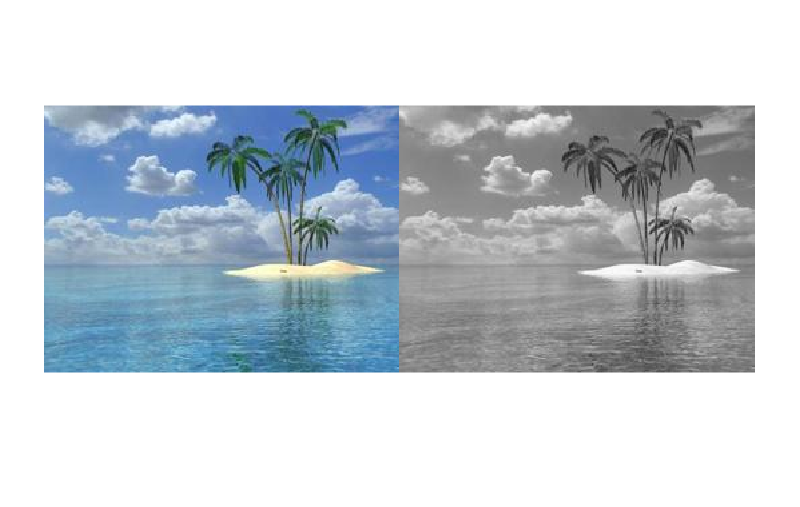

img = imread('ocean_with_trees_smaller.jpg');
grey_img = rgb2gray(img);

montage({img,grey_img});

Find energy matrix and display it as energy image.

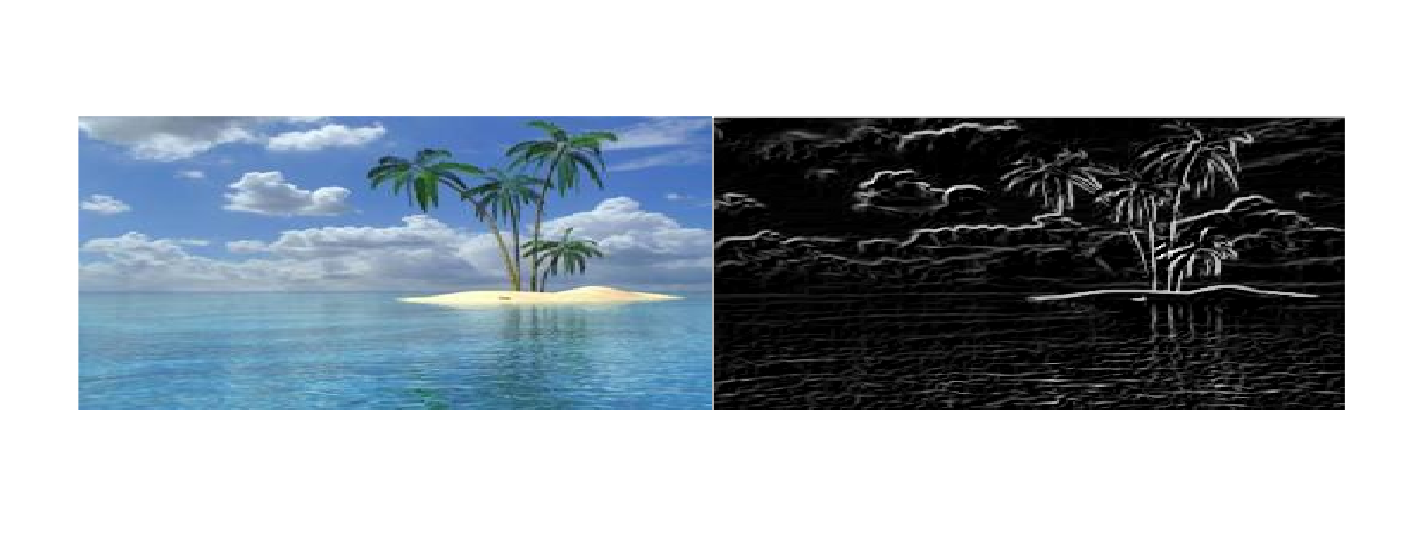

energy_matrix = find_energy(grey_img);

% we need to normalize values in the matrix to find in between 0 and 1, so
% that we can display it properly.
max_value = max(energy_matrix,[],"all");
energy_img = energy_matrix / max_value;

montage({img,energy_img});

Find M matrix (least energy seam) and K matrix (direction)

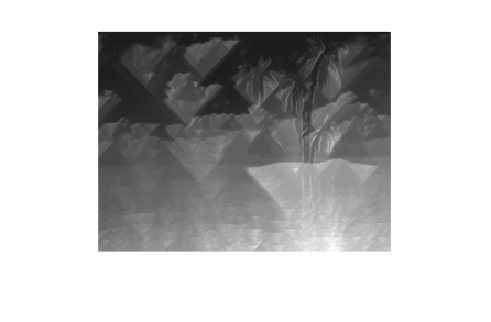

[least_energy,direction] = find_least_energy(energy_matrix);

% we need to normalize values in the matrix to find in between 0 and 1, so
% that we can display it properly.
max_value = max(least_energy,[],"all");
least_energy_img = least_energy / max_value;

imshow(least_energy_img);

Find and display best seam for each column.  We can use the slider to see the best seam for each column interactively.

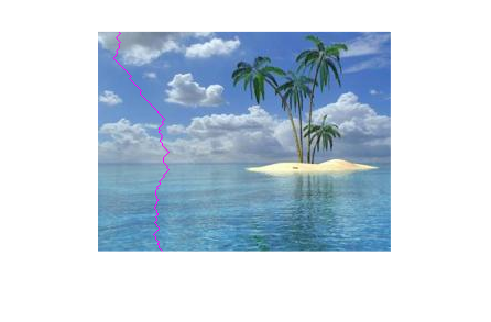

[m,n] = size(grey_img);
[e_min, k_min] = min(least_energy(m,:));

col =59;

path = get_seam_at(direction, col);
marked_img = mark_seam(img, path);

imshow(marked_img);

Remove seam : we can shrink or resize the image to make it small by removing the best seam with the lowest energy.

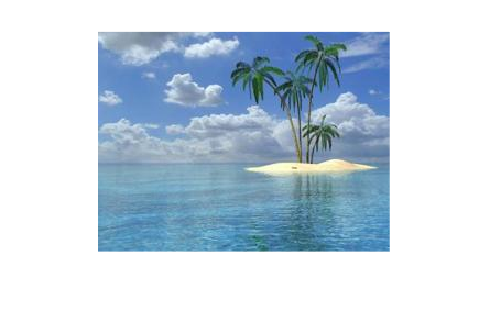

new_img = remove_seam(img, path);

imshow(new_img);

## The code up to this point shows general steps to 

- read image

- calculate the energy

- find the best seam

- remove the seam to shrink the image

### Each time to remove one seam takes time to compute. To make it a bit more interactive, we need to precompute seams and resulting images.  Once we have all resulting images precomputed, we can display it interactively.

### So we need to write code to precompute these results.

## For example, let's assume that we want to shrink our image by half in width (N column), so we can write a function to do all the steps mentioned above and loop N times.

Shrink image : 

n_examples = size(img,2)/2;
%n_examples = 50;

[shrink_imgs,marked_shrink_imgs] = shrink_image(img, n_examples);


Use separate section, so that we can re-play the results faster without having to re-compute again and again.

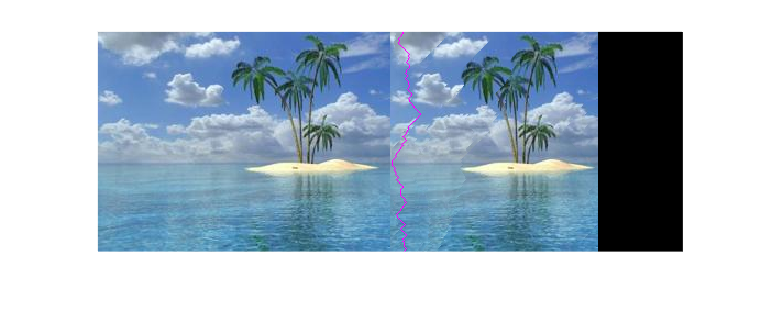

num_to_shrink =78;
%montage({img,cell2mat(marked_shrink_imgs(num_to_shrink))});
imshowpair(img,cell2mat(marked_shrink_imgs(num_to_shrink)),"montage");

# You need to write following functions to make the code above run successfully.

- function energy_matrix = find_energy(grey_img)

- function [least_E, dirs] = find_least_energy(E)

- function path = get_seam_at(dirs, j)

- function marked_img = mark_seam(img, path)

- function new_img = remove_seam(img, path)

- function [shrink_imgs,marked_shrink_imgs] = shrink_image(img, num_to_shrink)

Find energy matrix.  

This function is provided to you to get started. It should work as is.

function energy_matrix = find_energy(grey_img)
    Sx = fspecial('sobel');
    Dx = double(imfilter(grey_img,Sx,'conv'));

    Sy = Sx';
    Dy = double(imfilter(grey_img,Sy,'conv'));

    energy_matrix = sqrt(Dx.^2 + Dy.^2);
end

Compute the M matrix (least_E) and K matrix (dirs). This function compute the M matrix and K matrix as mentioned in the lecture. Note that the direction is changed to -1, 0, 1 instead of 1, 2, 3.

function [least_E, dirs] = find_least_energy(E)
    
    least_E = E; % Substitue E to least_E % 
    [r,c] = size(least_E);
    dirs = zeros(r,c); % Waiting for replacing the direction

    for i = 2:r
        for j = 1:c
            % Find minimum from the above 3 %
            if j == 1
                [minimum, k] = min([least_E(i-1,j), least_E(i-1,j+1)]);
                if k == 1
                    dirs(i,j) = 0;
                else
                    dirs(i,j) = 1;
                end
            elseif j == c
                [minimum, k] = min([least_E(i-1,j-1), least_E(i-1,j)]);
                if k == 1
                    dirs(i,j) = -1;
                else
                    dirs(i,j) = 0;
                end
            else
                [minimum, k] = min([least_E(i-1,j-1), least_E(i-1,j), least_E(i-1,j+1)]);
                if k == 1
                    dirs(i,j) = -1;
                elseif k == 2
                    dirs(i,j) = 0;
                else
                    dirs(i,j) = 1;
                end
            end
            % Compute M matrix (least_e) %
            least_E(i,j) = least_E(i,j) + minimum;
            % Record number of K matrix by index (-1, 0, 1)
        end
    end
end

Get seam at a specific column.  This function take a direction matrix and a specified column as input and returns the best seam or path for that column.

function path = get_seam_at(dirs, j)
    
    [r,~] = size(dirs);
    path = zeros(r,1);
    
    for i = r:-1:1
        if i == r
            path(i) = j;
            collect = dirs(i,j);
        else
            if collect == (-1)
                path(i) = j + collect;
                j = j - 1;
                collect = dirs(i,j);
            elseif collect == 0
                path(i) = j + collect;
                collect = dirs(i,j);
            else % collect = 1
                path(i) = j + collect;
                j = j + 1;
                collect = dirs(i,j);
            end
        end
    end
end

Mark seam function take an image and the path or seam as input and return the new marked image that show the seam with some specific color such as [255,0,255].

function marked_img = mark_seam(img, path)
    
    [r,~] = size(path);
    marked_img = img;

    img_red = marked_img(:,:,1);
    img_green = marked_img(:,:,2);
    img_blue = marked_img(:,:,3);

    for i = 1:r
       img_red(i,path(i)) = 255;
       img_green(i,path(i)) = 0;
       img_blue(i,path(i)) = 255;
    end
    marked_img = cat(3, img_red, img_green, img_blue);
end

Remove seam from image (one column less).  This function take an image and seam as input, and output a new image with one column less than before.

function new_img = remove_seam(img, path)

    [r,c,ch] = size(img);
    % Create the black background after it being cropped out
    new_img = ones(r,c-1,ch,"uint8");
    collect = 0;
    
    for i = 1:r
        for j = 1:c
        % If it doesn't match with a path, it will copy from img => new_img
            if j ~= path(i)
                % It will collect just only the column that's able to put
                % like col 1 2 3 .. n
                collect = collect + 1;
                new_img(i,collect,:) = img(i,j,:);
        % If it match with a path, it will continue
            else % j == path(i)
                continue
            end
        end
    % Recount it again for the next row
    collect = 0;
    end
end

Shrink image function takes an image and number of columns to shrink.  It precomputes the images from removed each seam one by one. It returns two cell arrays of images with different sizes so we can display interactively later on.

function [shrink_imgs,marked_shrink_imgs] = shrink_image(img, num_to_shrink)

    % Run until it reaches the given num
    for i = 1:num_to_shrink
        grey_img = rgb2gray(img);
        [m,~] = size(grey_img);
        energy_matrix = find_energy(grey_img);
        [least_E, dirs] = find_least_energy(energy_matrix);
        [~, k_min] = min(least_E(m,:));
        path = get_seam_at(dirs, k_min);
        % Use cell to help
        marked_shrink_imgs{i} = mark_seam(img, path);
        shrink_imgs{i} = remove_seam(img, path);
        img = shrink_imgs{i};
    end
end